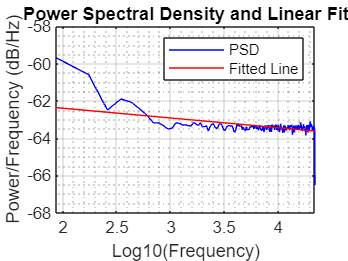

Determined Noise Type: White Noise
Predicted Noise Type: White Noise
Estimated Noise Standard Deviation: 0.10082


% Example usage:
fs = 44100; % Sampling frequency in Hz
duration = 10; % Duration of the audio signal in seconds
n_samples = duration * fs; % Total number of samples
desired_std = 0.1;

% Generate example audio signal (for testing)
%speech_signal = randn(1, n_samples) * 0.2; % Simulated low-energy speech
noise_gen = dsp.ColoredNoise('Color', 'pink', 'SamplesPerFrame', n_samples, 'NumChannels', 1); % Example pink noise
noise_signal = noise_gen();
% Normalize the pink noise to have a mean of 0 and standard deviation of 1
noise_signal = (noise_signal - mean(noise_signal)) / std(noise_signal);

% Scale the pink noise to the desired standard deviation
noise_signal = noise_signal * desired_std;

noise_signal = desired_std * transpose(randn(1, n_samples)); % Example white noise

audio_signal = signal + noise_signal; % Combine speech and noise

% sound(audio_signal, fs);
% pause(10);

% Predict the type and standard deviation of noise from the audio signal
vad_threshold = 12.5; % Energy threshold for VAD (adjust as needed)
[noise_type, noise_std] = predict_noise_type_and_std_from_audio(audio_signal, fs, vad_threshold);


% Initialize filter
P = 250;
m = 0:P-1; 
Rv = desired_std^2 * (m==0);
%Rdx = Rv';

% Autocorrelation of speech + noise
Rx = xcorr(audio_signal)';
Rx = Rx(floor(1+length(Rx)/2):end)/length(Rx);
Rx_matrix = toeplitz(Rx(1:P)); 

% Autocorrelation of speech
Rs = Rx(1:P) - Rv;
Rdx = Rs';

% Regularization term for stability
lambda = 0.1;
Rx_matrix_reg = Rx_matrix + lambda * eye(P);  % Add regularization

% Wiener filter coeff
h = Rx_matrix_reg \ Rdx;

% v = conv(audio_signal,h);
% 
% audio_signal = audio_signal - v(1:length(audio_signal));

s = conv(audio_signal,h);

audio_signal = s(1:length(audio_signal)) ;
%audio_signal = s ;

% Output processed audio frame
sound(audio_signal, fs);
% pause(10);
% 
% % Filtering
% filtered_signal = filter(h, 1, audio_signal);
% 
% % Ensure the output is the same length as the input
% filtered_signal = filtered_signal(1:length(audio_signal));
% 
% % Output processed audio frame
% sound(filtered_signal, fs);

function [noise_type, noise_std] = predict_noise_type_and_std_from_audio(audio_signal, fs, vad_threshold)
    % Function to predict the type and standard deviation of noise from an audio signal
    % audio_signal: The input audio signal (speech + noise)
    % fs: Sampling frequency in Hz
    % vad_threshold: Energy threshold for voice activity detection (VAD)

    % Define parameters for frame-based processing
    frame_length = 1024; % Frame length in samples
    frame_step = 512; % Frame step in samples
    num_frames = floor((length(audio_signal) - frame_length) / frame_step) + 1;

    % Initialize an array to hold noise-only segments
    noise_segments = [];

    % Process each frame
    for i = 1:num_frames
        % Extract the current frame
        start_index = (i-1) * frame_step + 1;
        end_index = start_index + frame_length - 1;
        frame = audio_signal(start_index:end_index);

        % Compute the energy of the current frame
        frame_energy = sum(frame .^ 2);

        % Check if the frame is noise-only (energy below the threshold)
        if frame_energy < vad_threshold
            % Append the noise-only frame to the noise_segments array
            noise_segments = [noise_segments; frame];
        end
    end

    % Check if we have enough noise-only segments
    if isempty(noise_segments)
        error('No noise-only segments found. Adjust the VAD threshold.');
    end

    % Concatenate noise-only segments into a single signal
    noise_signal = noise_segments(:);

    % Predict the type of noise from the extracted noise segments
    noise_type = predict_noise_type(noise_signal, fs);

    % Estimate the standard deviation of the noise
    noise_std = std(noise_signal);

    % Display the predicted noise type and standard deviation
    disp(['Predicted Noise Type: ', noise_type]);
    disp(['Estimated Noise Standard Deviation: ', num2str(noise_std)]);
end

function noise_type = predict_noise_type(noise_signal, fs)
    % Function to predict the type of noise (pink or white) based on PSD analysis
    % noise_signal: The recorded noise signal
    % fs: Sampling frequency in Hz

    % Compute the Power Spectral Density (PSD) using Welch's method
    [Pxx, f] = pwelch(noise_signal, 512, 256, 512, fs);

    % Convert the PSD to decibels
    Pxx_dB = 10*log10(Pxx);

    % Fit a linear model to the log-log PSD
    log_f = log10(f(2:end)); % Exclude the DC component (f=0)
    log_Pxx_dB = Pxx_dB(2:end); % Exclude the DC component (f=0)

    % Perform linear regression on the log-log plot
    p = polyfit(log_f, log_Pxx_dB, 1);

    % The slope of the fitted line indicates the noise type
    slope = p(1);

    % Define a threshold for determining the noise type
    % Pink noise typically has a slope around -3 dB/octave (-10 dB/decade)
    % White noise has a slope around 0 dB/octave
    threshold = -2.5;

    if slope < threshold
        noise_type = 'Pink Noise';
    else
        noise_type = 'White Noise';
    end

    % Plot the PSD and the fitted line for visualization
    figure;
    plot(log_f, log_Pxx_dB, 'b', 'DisplayName', 'PSD');
    hold on;
    plot(log_f, polyval(p, log_f), 'r', 'DisplayName', 'Fitted Line');
    title('Power Spectral Density and Linear Fit');
    xlabel('Log10(Frequency)');
    ylabel('Power/Frequency (dB/Hz)');
    legend show;
    grid on;
    grid minor;

    % Display the determined noise type
    disp(['Determined Noise Type: ', noise_type]);
end